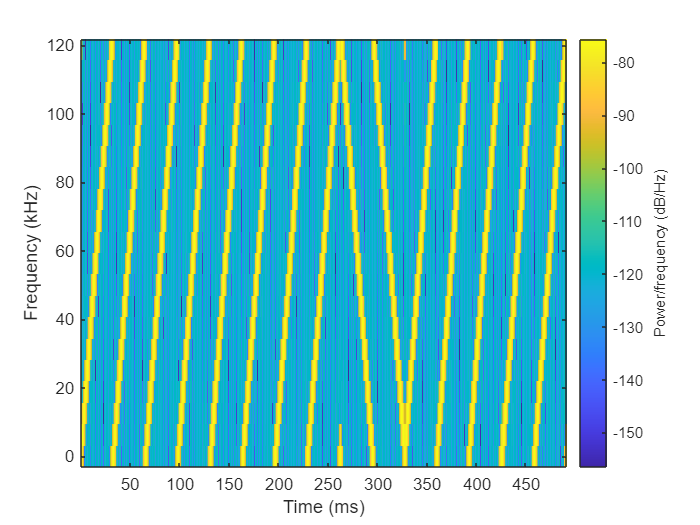

clear; clc;

SF = 12;       % Spreading factor
BW = 125e3;    % Bandwidth
Fs = 125e3;    % Sampling frequency
SNR = -15;     % Signal to Noise ratio (db)
num_samples = (2^SF)*Fs/BW;
data = [0 0 0 0 0 0 0 0 -1 -1 58 91 107 35 52]; % 0: Up chirp, -1: Down chirp
signal_data = zeros(length(data), num_samples);
clean_data = zeros(length(data), num_samples);

% Modulation
for i = 1:length(data)
    k = data(i);
    lora_symbol = zeros(1, num_samples);
    if k == -1      % Generate down-chirp
        k = 0;
        for n = 1:num_samples
            k = k+1;
            lora_symbol(n) = (1/(sqrt(2^SF)))*exp(-1i*2*pi*(k)*(k/(2^SF*2)));
        end
    else    % Generate symbol
        for n = 1:num_samples
            if k >= 2^SF        % Apply modulo
                k = k-2^SF;
            end
            k = k+1;
            lora_symbol(n) = (1/(sqrt(2^SF)))*exp(1i*2*pi*(k)*(k/(2^SF*2)));
        end
    end
    
    clean_data(i, :) = lora_symbol;

    % Add Gaussian white noise
    lora_symbol = awgn(lora_symbol, SNR, 'measured');
    signal_data(i, :) = lora_symbol;
end

seg_len = 20;
spectrogram(reshape(clean_data', 1, numel(clean_data))', seg_len, [], seg_len, Fs, 'yaxis');

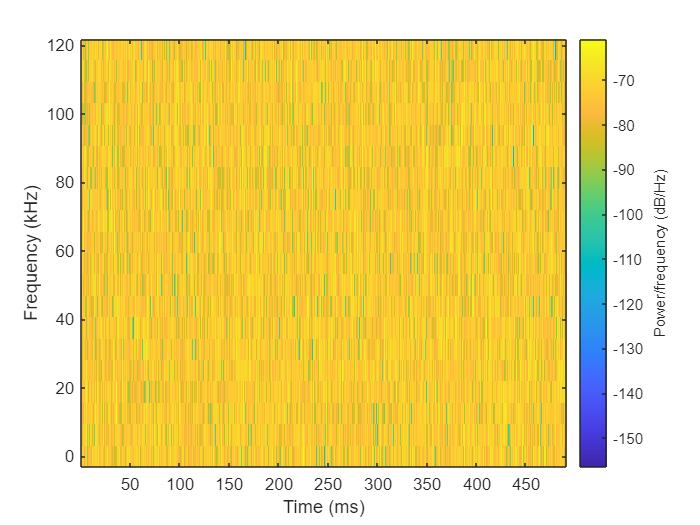

spectrogram(reshape(signal_data', 1, numel(signal_data))', seg_len, [], seg_len, Fs, 'yaxis');

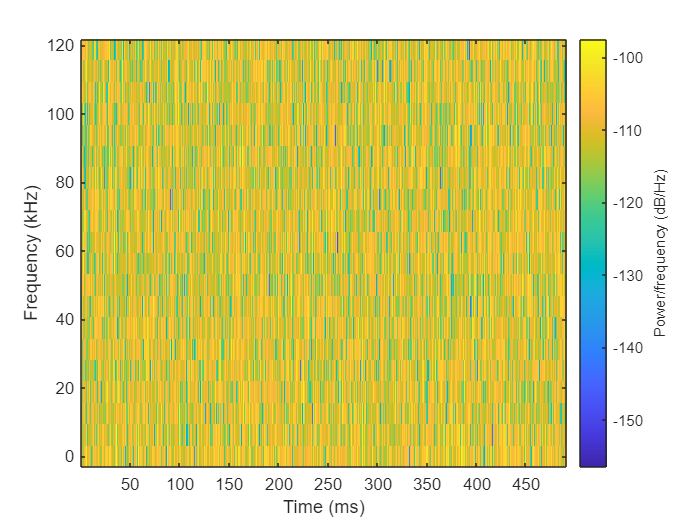

% Demodulation
received_data = reshape(signal_data, [], num_samples);  % Stores the received data, row-wise
base_down_chirp = zeros(1, num_samples);    % Will be used to demodulate the signal
dechirped_data = zeros(numel(received_data)/num_samples, num_samples);

% Generate the base-down chirp
k = 0;
for n = 1:num_samples
    if k >= 2^SF
        k = k-2^SF;
    end
    k = k + 1;
    base_down_chirp(n) = (1/(sqrt(2^SF)))*exp(-1i*2*pi*(k)*(k/(2^SF*2)));
end

payload = zeros(1, numel(received_data)/num_samples);   % Stores the transmitted data

% Perform demodulation symbol-wise (i.e. row-wise)
for i = 1:numel(received_data)/num_samples
    lora_symbol = received_data(i, :);
    
    dechirped = lora_symbol.*base_down_chirp;   % Demodulate the symbol
    dechirped_data(i, :) = dechirped;
    
    corrs = abs(fft(dechirped)).^2;             % Perform correlation
    
    % Obtain the correlated symbol
    [~, ind] = max(corrs);
    payload(i) = ind-1;
end

spectrogram(reshape(dechirped_data', 1, numel(dechirped_data))', seg_len, [], seg_len, Fs, 'yaxis');

% Compare the transmitted and received payload
[data(11:end); payload(11:end)]

ans =     58    91   107    35    52
    58    91   107    35    52


data

data =      0     0     0     0     0     0     0     0    -1    -1    58    91   107    35    52


payload

payload =            0           0           0           0           0           0           0           0        1205        3040          58          91         107          35          52
